robot = {};
robot.X = 50;
robot.Y = 60;
robot.deltaX = 1;
robot.deltaY = 1;

map = zeros(100, 100);

% x1 y1; x2 y2
square = [40, 30; 60, 70];

map(square(1,2):square(2,2), square(1,1)) = 1;
map(square(1,2), square(1,1):square(2,1)) = 1;
map(square(1,2):square(2,2), square(2,1)) = 1;
map(square(2,2), square(1,1):square(2,1)) = 1;

robot.Map = map;
boundary = getBoundary(robot.Map, robot.X, robot.Y);
boundaryDist = boundaryWithDistance(boundary, robot.X, robot.Y);

ans = 117


closest = closestUnexplored(boundary, robot.X, robot.Y)

closest =     50    70


closestVel = closestUnexploredWithVelocity(boundary, robot.X, robot.Y, robot.deltaX, robot.deltaY)

closestVel =     60    56



robotMap = binaryOccupancyMap(map);

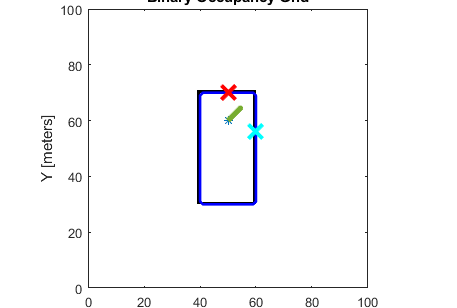

arrowMult = 5;

show(robotMap)
hold on
plot(robot.X, robot.Y, "*")
plot(boundary(:,2), boundary(:,1), "blue", "LineWidth",2)
plot(closest(1), closest(2), "x","color","red", "MarkerSize", 15, "LineWidth",3)
plot(closestVel(1), closestVel(2), "x","color","cyan", "MarkerSize", 15, "LineWidth",3)
quiver(robot.X, robot.Y, robot.deltaX * arrowMult, robot.deltaY * arrowMult, "LineWidth",4)
hold off

clear
map = rand(100, 100);
map(map==0) = 1;
drone = Drone(map, 50, 50, 7);

Warning!!! Max speed of drone is too great for the sensing capability currently set. The drone may fly faster than its sensing area.


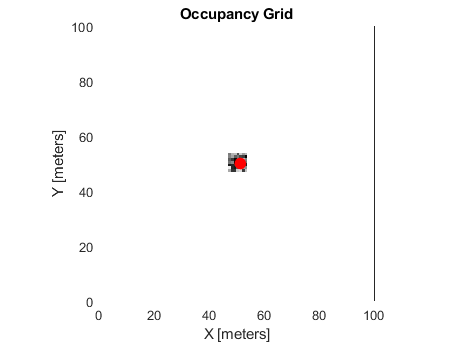

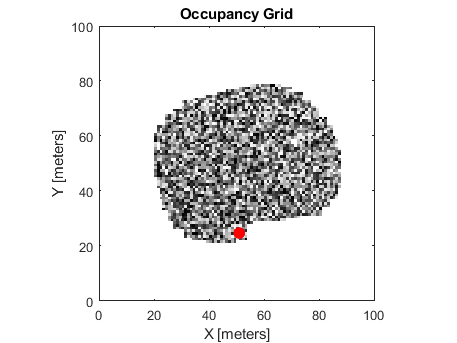

poses = [50, 50];
hold on
for i = 1:100
    boundary = drone.getBoundary();
    target = closestUnexploredWithVelocity(boundary, drone.X, drone.Y, drone.DeltaX, drone.DeltaY);
%     target = closestUnexplored(boundary, drone.X, drone.Y);
    targetX = target(1);
    targetY = target(2);
    count = 0;
    while ~drone.isNear(targetX,targetY)
        drone = drone.navigateWithSpeed(targetX,targetY, 0.6);
        drone.plot();
        pause(0.02);
        poses(end+1,:) = [drone.X, size(map,1)- drone.Y];
%         if count > 50
%             break;
%         end
%         count = count +1;
    end
end

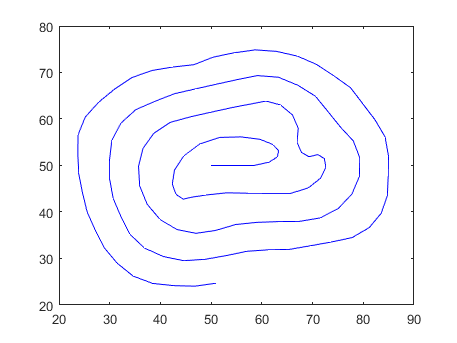

plot(poses(:,1), poses(:,2), "blue")

moves = drone.Moves

moves = 124

explored = length(drone.DroneMap(drone.DroneMap>0))

explored = 3061

total = size(drone.DroneMap, 1) * size(drone.DroneMap, 2)

total = 10000

percent = explored / total

percent = 0.3061

function boundary = getBoundary(robotMap, robotX, robotY)
    pixel = robotY;
    visible = robotMap(robotY, robotX);
    for i = robotY:robotY+100
        if robotMap(i, robotX) ~= visible
            pixel = i;
            break;
        end
    end
    boundary = bwtraceboundary(robotMap, [pixel, robotX], 'N');
end

function closest = closestUnexplored(boundary, robotX, robotY)
    closest = [0, 0];
    closestDistance = 100000;
    for i = 1:size(boundary, 1)
        newDist = distance([robotY, robotX], boundary(i,:));
        if newDist < closestDistance
            closestDistance = newDist;
            closest = [boundary(i,2), boundary(i,1)];
        end
    end
end

function boundaryDist = boundaryWithDistance(boundary, robotX, robotY)
    boundaryDist = boundary;
    size(boundary, 1)
    for i = 1:size(boundary, 1)
        boundaryDist(i,3) = distance([robotY, robotX], boundary(i,:));
    end
end

function closest = closestUnexploredWithVelocity(boundary, robotX, robotY, deltaX, deltaY)
%     disp("find closest with vel")
    closest = [0, 0];
    closestDistance = 1000000;
    for i = 1:size(boundary, 1)
        deltaRobot = [deltaX, deltaY];
        if norm(deltaRobot) ~=0
            normRobot = deltaRobot / norm(deltaRobot);
        else
            normRobot = [0, 0];
        end
        
        pointDelta = [boundary(i,2)-robotX, boundary(i,1)-robotY];
        normPoint = pointDelta / norm(pointDelta);
        
        dist = distance([robotY, robotX], boundary(i,:));

        startDist = distance(boundary(i,:), [50 50]);
        
        newDist = distanceVelocityHeuristic(dist, normRobot, normPoint, startDist);
        
        if newDist < closestDistance
            closestDistance = newDist;
            closest = [boundary(i,2), boundary(i,1)];
        end
    end
end

function heuristic = distanceVelocityHeuristic(dist, normRobot, normPoint, startDist)
    velocityCoeff = 2;
%     normRobot = normRobot;
%     normPoint = normPoint;
    diffX = abs(normRobot(1) - normPoint(1));
    diffY = abs(normRobot(2) - normPoint(2));
    heuristic = dist + startDist + diffX * velocityCoeff + diffY * velocityCoeff;
end

function dist = distance(a, b)
    dist = sqrt((a(1) - b(1)) ^ 2 + (a(2) - b(2)) ^ 2);
end